# PV emulator curves

First, we are going to test the equations:


$$I=N_PI_{PH}-N_PI_S[exp(q(V/N_S+iR_s/N_P)/kT_{cell}A)-1]-(N_PV/N_S+iR_S)/R_{SH}$$


We want to plot the curves for different temperatures and different irradiation

for that we use the pv_math function, which is a script that  uses the samle mathematical model as what is implemented in the PV model simulink...

type pv_math.m

function I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i)
    q = 1.6e-19;                          % Electron charge
    k = 1.38e-23;                         % Boltzmann constant
    Tcell = 273+T;                        % Cell temperature in Kelvin
%     vt=(A*k*Tcell*Ns)/q;                  % Thermal voltage Equation(5)
        
    Isc_T = Isc+((Isc*(Ki/100))*(T-25));  % Isc temperature coef Equation(6)
    Voc_T = Voc+((Voc*(Kv/100))*(T-25));  % Voc temperature coef Equation(7)
    Is = Isc_T/(exp(Voc_T/((A*k*Tcell*Ns)/q))-1);         % Reverse saturation current Equation(8)
    Iph = Isc_T*(G/1000);                 % Photon current Equation(9)
    
    % Single diode model output current Equation(4)
    I = Np*Iph-Np*Is*( exp(q*(V/Ns+i*Rs/Np)/(k*Tcell*A) )  -1) -(Np*V/Ns+i*Rs)/Rsh ;
    %I=Np*Iph-Np*Is*(exp(q*V/(Ns*k*Tcell*A))-1);

%     q = 1.6e-19;                          % Electron charge
%     k = 1.38e-23;                         % Boltzmann constant
%     Tcell = 273+T; 

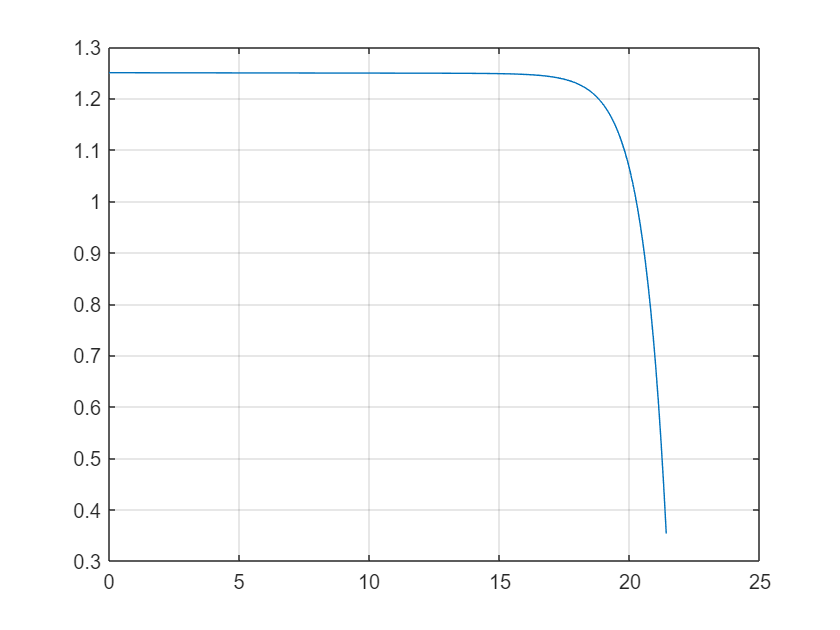

G=1000;
T=25;
Isc=1.25;
Voc=21.7;
A=0.97;
Rs=1.3;
Rsh=362;
Ns=36;
Np=1;
k_i=0.102;
k_v=-0.36099;
i=0;
V=0:0.1:21.4;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,k_i,k_v,V,i);
figure()
plot(V,I)
grid on

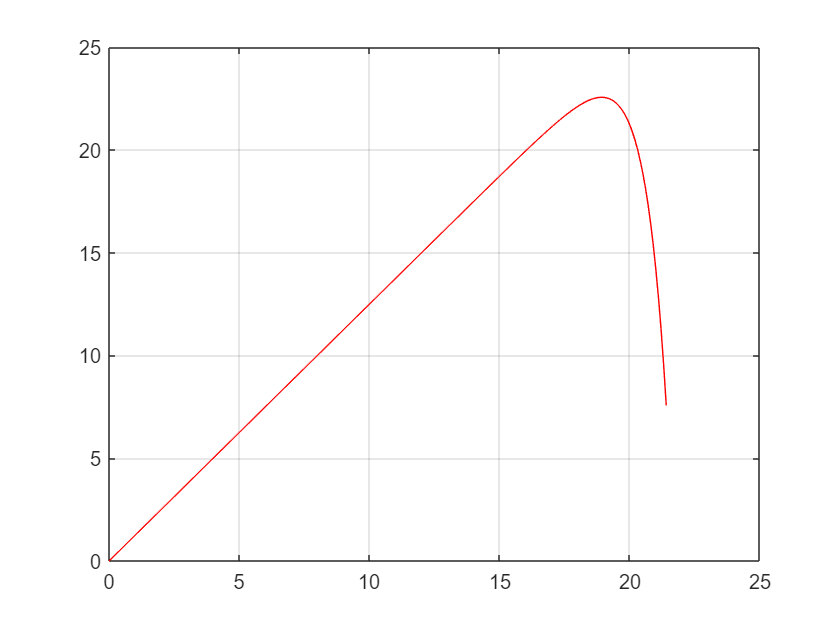

figure()
plot(V,V.*I,'r')
grid on

## IonSat MSP

Using the values of the MSP IonSat Solar panel 4S4P , The value of A is found from this article Tsai, H. L., Tu, C. S., & Su, Y. J. (2008, October). Development of generalized photovoltaic model using MATLAB/SIMULINK. In *Proceedings of the world congress on Engineering and computer science* (Vol. 2008, pp. 1-6).

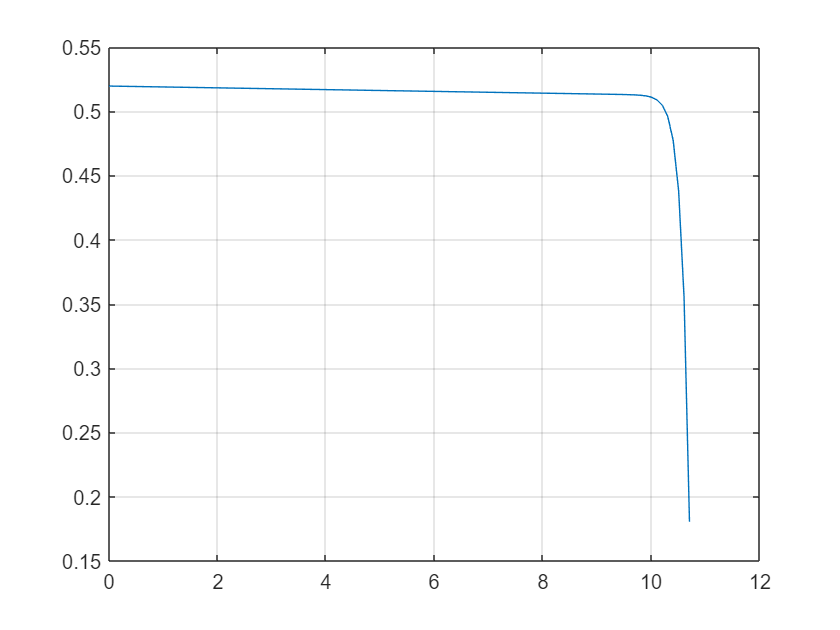

Ns=4;
Np=1;
G=1000;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
figure()
plot(V,I)
grid on

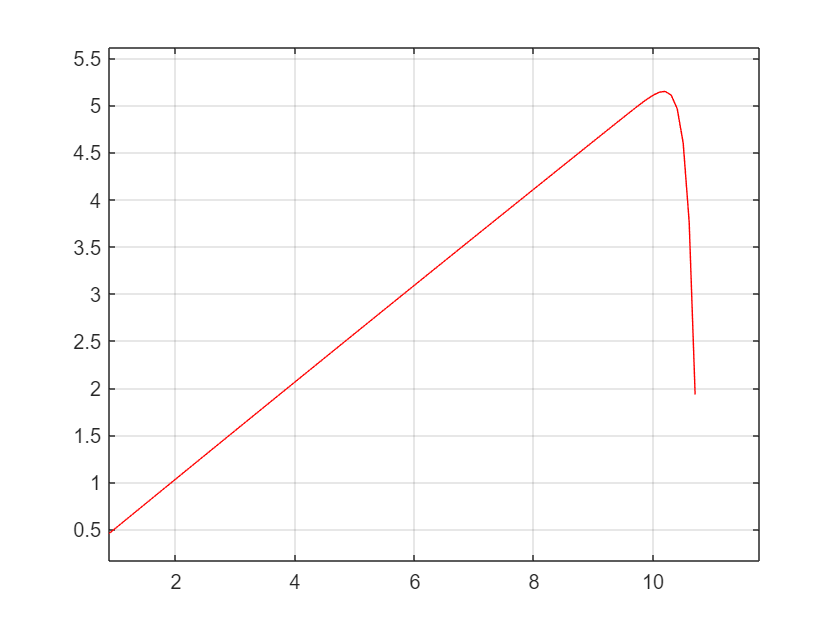

figure()
plot(V,V.*I,'r')
grid on

### Variation of Temperature

I-V

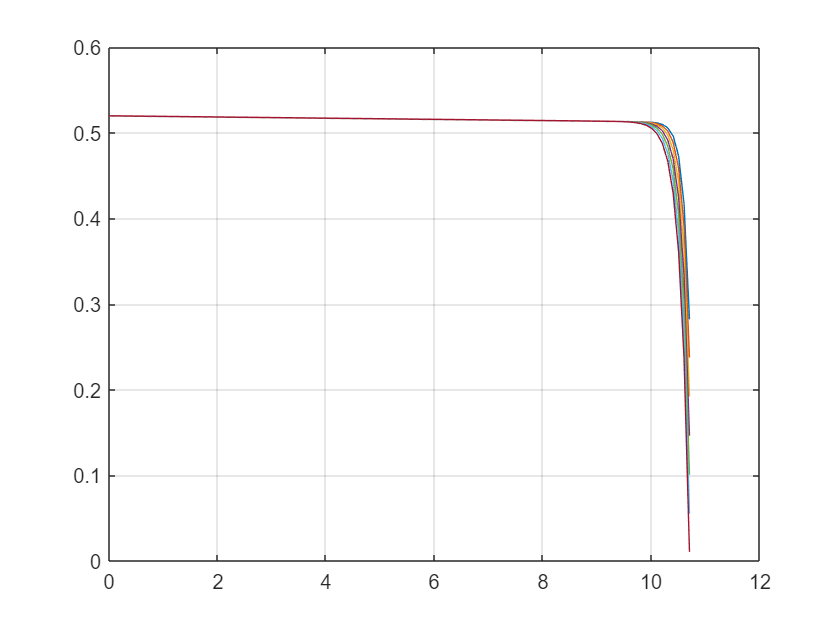

Ns=4;
Np=1;
G=1000;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc;
T=-20:20:100;
figure()
% for j = 1:1
%for j = 1:length(T)
for T=-20:20:100
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,I)
hold on
grid on
end

P-V

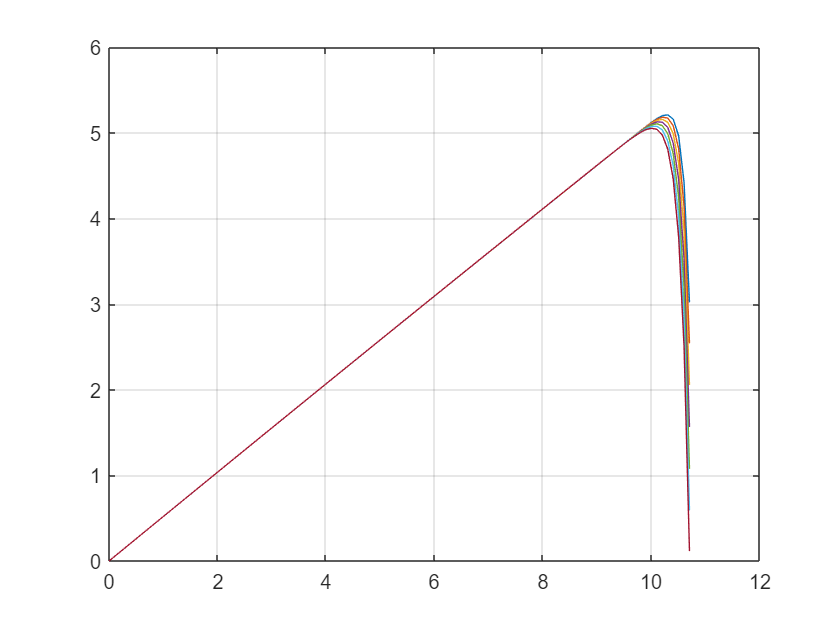

Ns=4;
Np=1;
G=1000;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc;
T=-20:20:100;
figure()
for T=-20:20:100
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,V.*I)
hold on
grid on
end

### Variation with irradiance

I-V

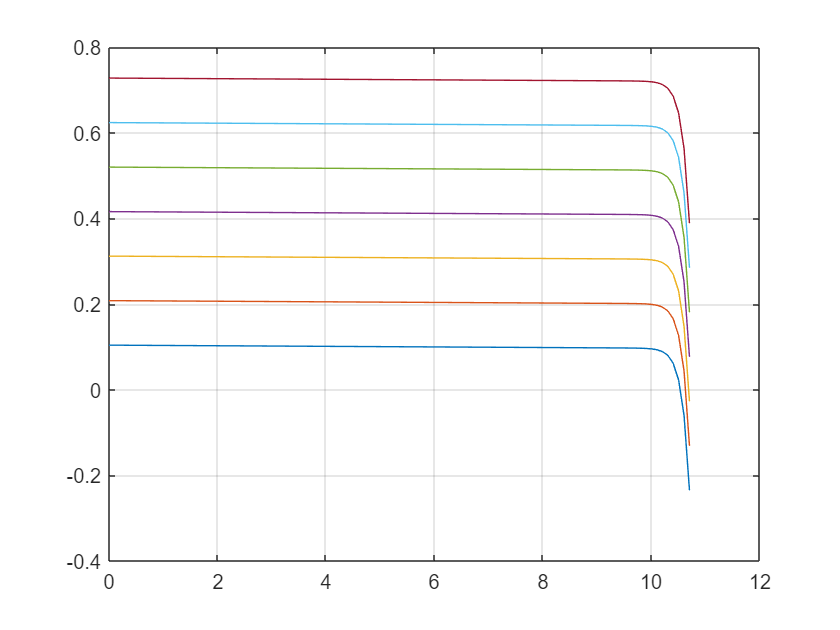

Ns=4;
Np=1;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc;
figure()
for G=200:200:1400
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,I)
hold on
grid on
end

P-V

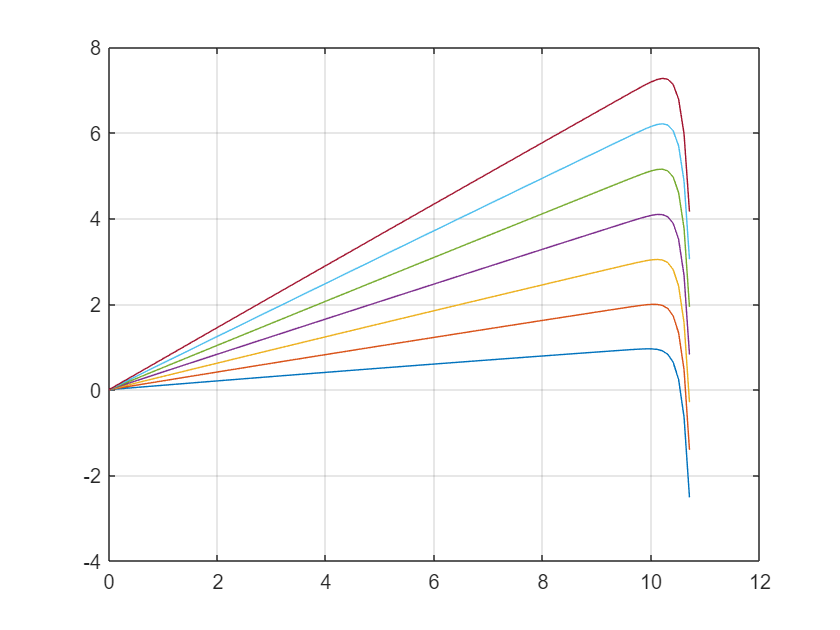

Ns=4;
Np=1;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc;
figure()
for G=200:200:1400
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,V.*I)
hold on
grid on
end